# PID Controller Tuning

Create a mathematical model of the system based on sampled data and tune a PID controller.

## System Identification

The model is identified from sampled data with an [Autoregressive Exogenous model](https://apmonitor.com/dde/index.php/Main/AutoRegressive):

y(t)=c+a1y(t−1)+a2y(t−2)+...+apy(t−p)+e(t)

% Dataset selection (time, input, output columns)
dataset = "/Users/valeriynovytskyy/Desktop/system-identification/rotation3.csv";

% Time step for discretization (seconds)
timeStep = 0.01;

% Time range selection (seconds)
startTime = 51.8;
endTime = 121;

% Gaussian filter for measurements (samples)
smoothing = 19;

% Model parameters
measurementTaps = 2;
inputTaps = 2;
delayTimeSteps = 1;

% Load data
data = readtable(dataset);
time = data{:, 1};
inputs = data{:, 2};
measurements = data{:, 3};

% Resample to fixed time step
[uniqueTime, ~, uniqueIdx] = unique(time);
avgInputs = accumarray(uniqueIdx, inputs, [], @mean);
avgMeasurements = accumarray(uniqueIdx, measurements, [], @mean);

regularTime = min(uniqueTime):timeStep:max(uniqueTime);
inputs = interp1(uniqueTime, avgInputs, regularTime, 'linear', 'extrap');
measurements = interp1(uniqueTime, avgMeasurements, regularTime, 'linear', 'extrap');
time = regularTime;

% Select time range
mask = (time >= startTime) & (time <= endTime);
time = time(mask);
inputs = inputs(mask);
measurements = measurements(mask);

% Filter
if smoothing > 0
    measurements = smoothdata(measurements, 'gaussian', smoothing);
end

% Estimate model

measurements = measurements(:);
inputs = inputs(:);
numberOfSamples = numel(measurements);
maxDelay = max(measurementTaps, inputTaps + delayTimeSteps);
numberOfParameters = measurementTaps + (inputTaps + 1);
numberOfRows = numberOfSamples - maxDelay;
samplesMatrix = zeros(numberOfRows, numberOfParameters);

% Measurement coefficients: -y[k-1], -y[k-2], ..., -y[k-measurementTaps]
for j = 1:measurementTaps
    samplesMatrix(:, j) = -measurements((maxDelay - j + 1) : (numberOfSamples - j));
end

% Input coefficients: u[k-delay], u[k-delay-1], ..., u[k-delay-inputTaps]
for j = 0:inputTaps
    samplesMatrix(:, measurementTaps + 1 + j) = ...
        inputs((maxDelay - delayTimeSteps - j + 1) : (numberOfSamples - delayTimeSteps - j));
end

% Target vector corresponds to y[k] for k = maxDelay ... end
targetVector = measurements((maxDelay + 1) : numberOfSamples);

% Least-squares solution: samplesMatrix * weights = targetVector
weights = samplesMatrix \ targetVector;

% Split into parameters
measurementCoefficients = weights(1:measurementTaps);
inputCoefficients = weights(measurementTaps+1:end);

% Validation
predictions = samplesMatrix * weights;
residuals = targetVector - predictions;
variance = sum((targetVector - mean(targetVector)).^2);

if variance > 0
    fit = 100 * (1 - sum(residuals.^2) / variance);
else
    fit = 100 * double(all(residuals == 0));
end

fprintf("Fit = %.4f%%\n", fit);

Fit = 100.0000%


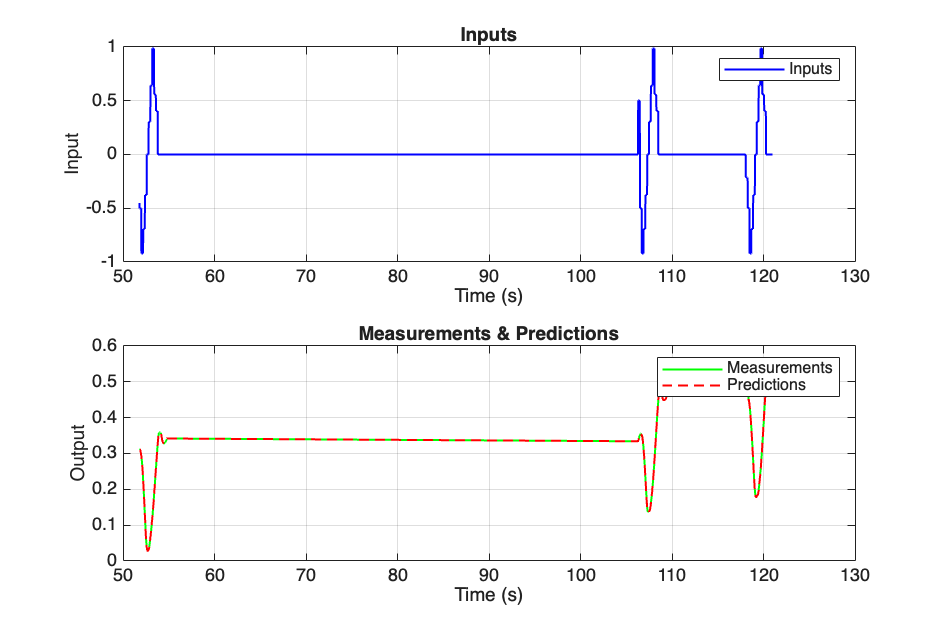


figure('Position', [100, 100, 1200, 800]);

% Plot inputs over time

subplot(2, 1, 1);
plot(time, inputs, 'b-', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Input');
title('Inputs');
grid on;
legend('Inputs');

% Plot measurements and predictions over time

subplot(2, 1, 2);
plot(time, measurements, 'g-', 'LineWidth', 1); hold on;
plot(time(maxDelay+1:end), predictions, 'r--', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Output');
title('Measurements & Predictions');
grid on;
legend('Measurements', 'Predictions');


% Transfer Function

measurementCoefficients = measurementCoefficients(:).'; 
inputCoefficients = inputCoefficients(:).';

num = inputCoefficients;
den = [1, measurementCoefficients];

fprintf("Transfer Function:\n\n");

Transfer Function:



fprintf("       %.6fs^2 + %.6fs + %.6f\n", inputCoefficients(1), inputCoefficients(2), inputCoefficients(3));

       0.000237s^2 + -0.000043s + 0.000040


fprintf("G(s) = %s\n", repmat('─',1,50));

G(s) = ──────────────────────────────────────────────────


fprintf("       s^2 + %.6fs + %.6f\n\n", measurementCoefficients(1), measurementCoefficients(2));

       s^2 + -1.962740s + 0.962744




% Discrete State Space Model

measurementCoefficientCount = length(measurementCoefficients);
numberOfInputTaps           = length(inputCoefficients) - 1;
inputDelaySteps             = max(0, delayTimeSteps);
inputLagBufferLength        = inputDelaySteps + numberOfInputTaps;
numberOfStates              = measurementCoefficientCount + inputLagBufferLength;

A = zeros(numberOfStates, numberOfStates);

if measurementCoefficientCount > 0
    % Measurement autoregression
    A(1, 1:measurementCoefficientCount) = -measurementCoefficients;
    if measurementCoefficientCount > 1
        % Shift measurement history
        A(2:measurementCoefficientCount, 1:measurementCoefficientCount-1) = ...
            eye(measurementCoefficientCount-1);                                    
    end
end

if inputLagBufferLength > 1
    % Shift inputs
    A(measurementCoefficientCount+2:end, measurementCoefficientCount+1:end-1) = ...
        eye(inputLagBufferLength-1);                                               
end

B = zeros(numberOfStates, 1);

if inputLagBufferLength >= 1
    B(measurementCoefficientCount + 1, 1) = 1;
end

% Accumulate measurements depency on inputs
directFeedthroughGain = 0;
lagOneGainToOutput    = 0;

for tapIndex = 0:numberOfInputTaps
    tapLag  = inputDelaySteps + tapIndex;
    tapCoef = inputCoefficients(tapIndex + 1);

    if tapLag == 0
        % Input affects output directly (no lag)
        directFeedthroughGain = directFeedthroughGain + tapCoef;
    elseif tapLag == 1
        % Input affects output next timeStep
        lagOneGainToOutput     = lagOneGainToOutput + tapCoef;
    else
        % State holds u(k - tapLag)
        bufferStateIndex = measurementCoefficientCount + tapLag;
        if bufferStateIndex <= numberOfStates
            A(1, bufferStateIndex) = A(1, bufferStateIndex) + tapCoef;
        else
            warning('Tap (lag=%d) exceeds state size (%d); skipping.', tapLag, numberOfStates);
        end
    end
end

if lagOneGainToOutput ~= 0
    % y(k+1) += (lag1)*u(k)
    B(1,1) = B(1,1) + lagOneGainToOutput;
end

C  = zeros(1, numberOfStates);  C(1,1) = 1;
D  = directFeedthroughGain;
Q  = eye(numberOfStates) * 1e-6;
R  = var(measurements - mean(measurements)) * 1e-3;
P0 = eye(numberOfStates) * 1e-2;

x0 = zeros(numberOfStates, 1);

if measurementCoefficientCount > 0
    % y(k), y(k-1), ...
    x0(1:measurementCoefficientCount) = measurements(1);                           
end

for lag = 1:inputLagBufferLength
    % u(k - lag)
    x0(measurementCoefficientCount + lag, 1) = inputs(1);
end

fprintf("Discrete State-Space Model:\n\n");

Discrete State-Space Model:



A

A =     1.9627   -0.9627         0   -0.0000    0.0000
    1.0000         0         0         0         0
         0         0         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0


B

B =     0.0002
         0
    1.0000
         0
         0


C

C =      1     0     0     0     0


D

D = 0

Q

Q = 1.0e-06 *

    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000


R

R = 4.3091e-06

P0

P0 =     0.0100         0         0         0         0
         0    0.0100         0         0         0
         0         0    0.0100         0         0
         0         0         0    0.0100         0
         0         0         0         0    0.0100


x0

x0 =     0.3115
    0.3115
   -0.4500
   -0.4500
   -0.4500


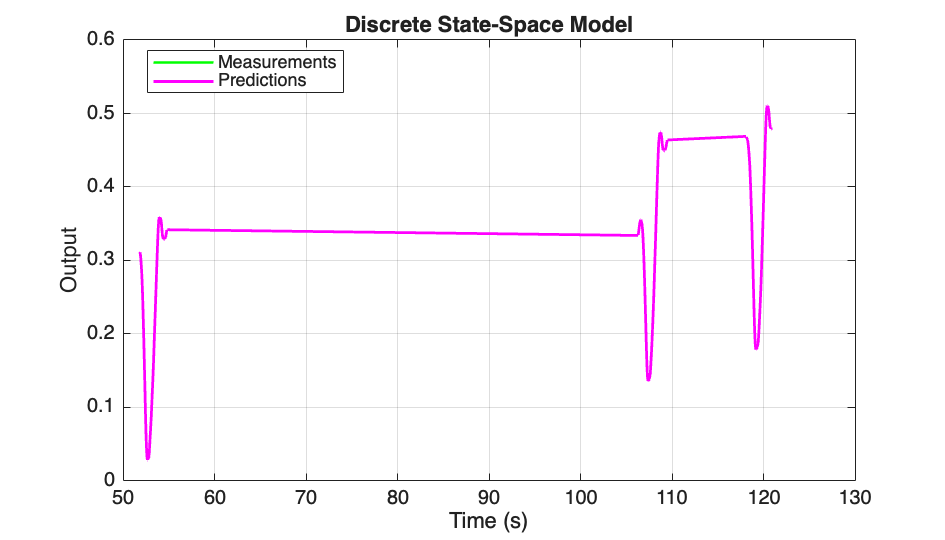


% Kalman filter

inputs = inputs(:);
measurements = measurements(:);
numberOfSamples = length(inputs);

predictions = zeros(numberOfSamples, 1);
output = zeros(numberOfSamples, 1);
gains = zeros(numberOfStates, numberOfSamples);
identity = eye(numberOfStates);

% Initialize
state = x0(:);
covariance = P0;

for sampleIndex = 1:numberOfSamples
    % Predict
    % y = Cx + Du
    predictions(sampleIndex) = C * state + D * inputs(sampleIndex);

    % Update gain
    gain = (covariance * C') / (C * covariance * C' + R);
    gains(:,sampleIndex) = gain;

    % Correct state
    error = measurements(sampleIndex) - predictions(sampleIndex);
    state = state + gain * error;

    % Correct covariance
    covariance = (identity - gain * C) * covariance * (identity - gain * C)' + gain * R * gain';

    % Output
    output(sampleIndex) = C * state + D * inputs(sampleIndex);

    % Update state
    % x = A * x + B * u
    state = A * state + B * inputs(sampleIndex);

    % Update covariance
    % P = A * P * A' + Q
    covariance = A * covariance * A' + Q;
end

% Plot State-Space Model
figure('Color','w','Position',[100 100 980 560]);
plot(time, measurements, 'g-', 'LineWidth', 1.2);
hold on;
plot(time, output, 'm-', 'LineWidth', 1.4);
grid on;
xlabel('Time (s)'); ylabel('Output');
title('Discrete State-Space Model');
legend('Measurements','Predictions','Location','best');

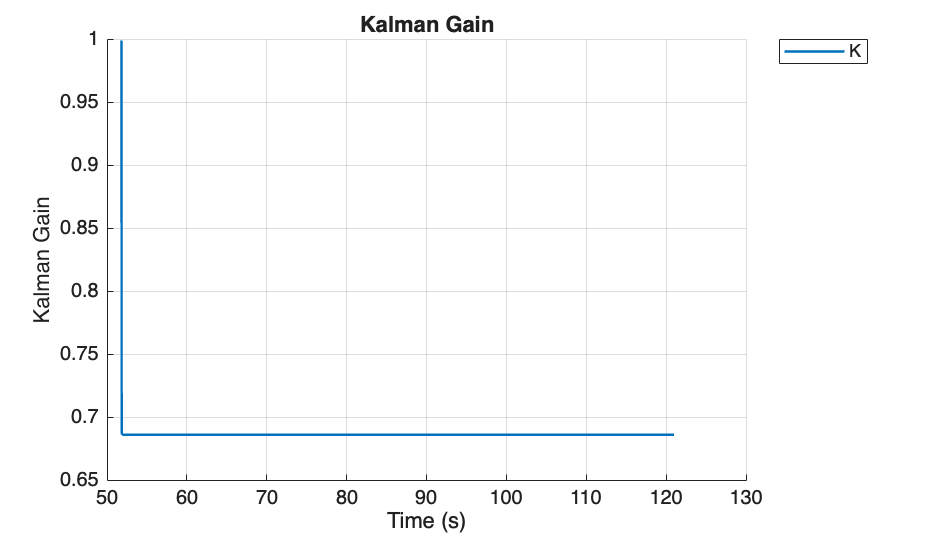


numStates = size(gains, 1);

figure('Color','w','Position',[150 150 980 560]);
hold on; grid on;

plot(time, gains(1, :), 'LineWidth', 1.2, 'DisplayName', 'K');

xlabel('Time (s)');
ylabel('Kalman Gain');
title('Kalman Gain');
legend('show', 'Location', 'bestoutside');

## PID Tuning

Configure the PID controller tuning parameters.

% Select a controller type
controllerType = "PID";

% Responsiveness (0 = Slower, 1 = Faster)
responsiveness = 0;

% Transient Behavior (0 = Aggressive, 1 = Robust)
transientBehavior = 1;

% Velocity Influence (PIV-only, 0 = No Damping, 2 = Max Damping)
velocityInfluence = 0

velocityInfluence = 0


% Targets
targetOvershoot     = max(5, 50*(1 - transientBehavior));
targetSettlingTime  = 0.1 + 2.0*(1 - responsiveness);
targetRiseTime      = 0.05 + 0.5*(1 - responsiveness);

% Initial Gains
switch controllerType
    case "P"
        Kp = 1.0; Ki = 0.0; Kd = 0.0; Kv = 0.0;
    case "PI"
        Kp = 1.0; Ki = 0.5; Kd = 0.0; Kv = 0.0;
    case "PID"
        Kp = 1.0; Ki = 0.5; Kd = 0.1; Kv = 0.0;
    case "PD"
        Kp = 1.0; Ki = 0.0; Kd = 0.1; Kv = 0.0;
    case "PIV"
        Kp = 1.0; Ki = 0.5; Kd = 0.0; Kv = 0.3;
    otherwise
        error("Unknown controller type: %s", controllerType);
end

theta0 = log([max(Kp, eps), max(Ki, eps), max(Kd, eps), max(Kv, eps)]);

% Inline Tuning Objective

objective = @(theta) localObjectiveToy(theta, controllerType, ...
    responsiveness, transientBehavior, ...
    targetRiseTime, targetSettlingTime, targetOvershoot, velocityInfluence);

opts = optimset('Display','none');
thetaOpt = fminsearch(objective, theta0, opts);

K = exp(thetaOpt(:))'; % [Kp, Ki, Kd, Kv]
Kp = K(1); Ki = K(2); Kd = K(3); Kv = K(4);

switch controllerType
    case "P"
        Ki = 0.0; Kd = 0.0; Kv = 0.0;
    case "PI"
        Kd = 0.0; Kv = 0.0;
    case "PD"
        Ki = 0.0; Kv = 0.0;
    case "PID"
        Kv = 0.0;
    case "PIV"
        Kd = 0.0;
end

% Step Response
[t, y, riseTime, settlingTime, overshoot] = computeStepResponse(Kp, Ki, Kd, Kv);

% Discretization
[Kp_d, Ki_d, Kd_d, Kv_d] = continuousToDiscrete(Kp, Ki, Kd, Kv, timeStep);

% Results

fprintf("\nContinuous:\n");


Continuous:


fprintf("Kp = %.4f\n", Kp);

Kp = 1.0010



if Ki > 0, fprintf("Ki = %.4f\n", Ki); end

Ki = 1.4039


if Kd > 0, fprintf("Kd = %.4f\n", Kd); end

Kd = 10.0001


if Kv > 0, fprintf("Kv = %.4f\n", Kv); end

fprintf("\nDiscrete:\n");


Discrete:


fprintf("Kp = %.4f\n", Kp_d);

Kp = 1.0010



if Ki > 0, fprintf("Ki = %.4f\n", Ki_d); end

Ki = 0.0070


if Kd > 0, fprintf("Kd = %.4f\n", Kd_d); end

Kd = 2000.0132


if Kv > 0, fprintf("Kv = %.4f\n", Kv_d); end

fprintf("\nRise Time: %.3f seconds\n", riseTime);


Rise Time: 0.010 seconds


fprintf("Settling Time: %.3f seconds\n", settlingTime);

Settling Time: 0.340 seconds


fprintf("Overshoot: %.1f%%\n", overshoot);

Overshoot: 0.0%


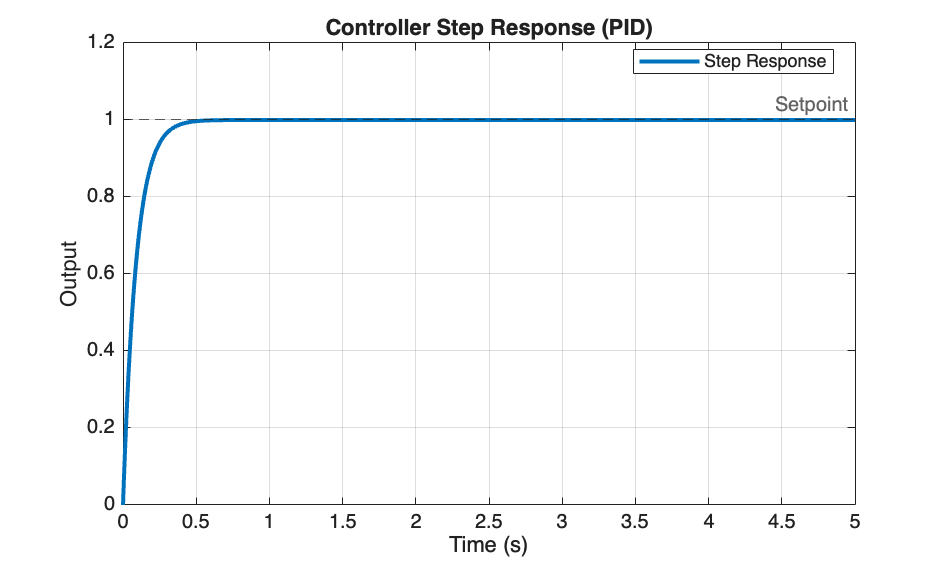


% Plot
plotStepResponse(t, y, controllerType);


% Helper functions

function cost = localObjectiveToy(theta, controllerType, responsiveness, transientBehavior, targetRiseTime, targetSettlingTime, targetOvershoot, velocityInfluence)
    Kp = exp(theta(1));
    Ki = exp(theta(2));
    Kd = exp(theta(3));
    Kv = exp(theta(4));

    switch controllerType
        case "P"
            Ki = 0; Kd = 0; Kv = 0;
        case "PI"
            Kd = 0; Kv = 0;
        case "PD"
            Ki = 0; Kv = 0;
        case "PID"
            Kv = 0;
        case "PIV"
            Kd = 0;
    end

    KpTuned = Kp * (0.5 + responsiveness);
    KiTuned = Ki * (0.5 + transientBehavior);
    KdTuned = Kd * (0.5 + responsiveness);
    KvTuned = Kv * (0.5 + transientBehavior);

    dampingBundle = KdTuned + velocityInfluence * KvTuned;

    cost = abs(KpTuned - targetRiseTime) ...
         + abs(KiTuned - targetSettlingTime) ...
         + abs(dampingBundle - targetOvershoot);
end

function [Kp_d, Ki_d, Kd_d, Kv_d] = continuousToDiscrete(Kp, Ki, Kd, Kv, Ts)
    Kp_d = Kp;
    Ki_d = Ki * Ts/2;
    Kd_d = Kd * 2/Ts;
    Kv_d = Kv * 2/Ts;
end

function [t, y, riseTime, settlingTime, overshoot] = computeStepResponse(Kp, Ki, Kd, Kv)
    t = linspace(0, 5, 1000);
    alpha = 0.8;
    damping = Kd + alpha*Kv;
    y = 1 - exp(-t * max(Kp, 1e-6)) .* cos(t * max(Ki, 1e-6)) .* exp(-t * max(damping, 1e-6));
    y = min(max(y, 0), 1.2);

    yFinal = y(end);
    y10 = 0.1 * yFinal;
    idxRise = find(y >= y10, 1, 'first');
    if isempty(idxRise), riseTime = 0; else, riseTime = t(idxRise); end

    tol = 0.02 * abs(yFinal);
    idxSettle = find(abs(y - yFinal) > tol, 1, 'last');
    if isempty(idxSettle), settlingTime = 0; else, settlingTime = t(idxSettle); end

    overshoot = max(0, (max(y) - yFinal) / max(yFinal, 1e-6) * 100);
end

function plotStepResponse(t, y, controllerType)
    figure('Color','w','Position',[100 100 900 540]);
    plot(t, y, 'LineWidth', 2); hold on;
    yline(1, '--', 'Setpoint', 'Alpha', 0.7);
    grid on;
    xlabel('Time (s)');
    ylabel('Output');
    title(sprintf('Controller Step Response (%s)', controllerType));
    legend('Step Response','Location','best');
end